## Preparation

### Load the scripts

addpath("script");

### Set up the initial image

load 'data/mr_image.mat';

image = single(mrVolume(:, :, 90));

### Define constant parameters

size_image = size(image);
center = (size_image + 1) / 2;

## Task 1

Rotate the image repeatedly by 3 degrees and plot the differences in pixel values

### Rotations

% Define rotation parameters
rotation_angles = -150:3:150;

% Initialize result
image_ssds_rotation = zeros(size(rotation_angles));
for i = 1:length(rotation_angles)
    % Rotate the image
    transformation_matrix = makeTransf_2D_center(rotation_angles(i), 0, 0, 1, 1, center);
    image_transformed = transform_image_2D(transformation_matrix, image, "linear");
    
    % Calculate the pixel differences
    image_diff = image - image_transformed;
    image_ssds_rotation(i) = sum(image_diff(:).^2);
end

#### Plot the pixel differences

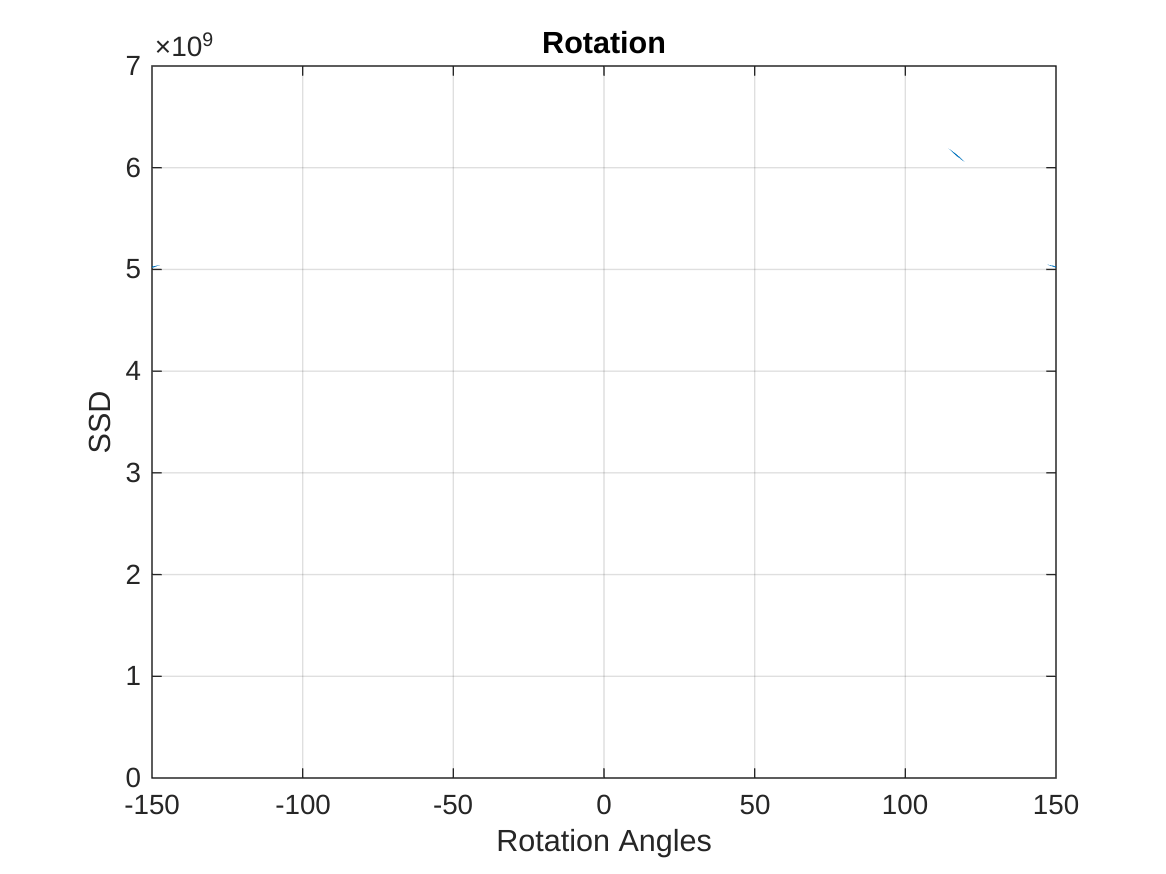

plot(rotation_angles, image_ssds_rotation)
xlabel("Rotation Angles")
ylabel("SSD")
title("Rotation")
grid on

#### Plot interpretation

The plot is has its minimum at the x-value 0 where no change is applied and symmetric. The more you rotate the image, the larger is the difference from the original image. The maximum is reached at around +- 90 degrees which makes sense considering that at 90 degrees rotation the the oval shape of the skull has the least overlapping area with its original position.

### Translations

translation_distances = -150:1:150;

% Initialize result
image_ssds_translation = zeros(size(translation_distances));
for i = 1:length(translation_distances)
    % Translate the image always by 1 (x^2 + y^2 = translation_distance^2 where x = y)
    translation_x = sqrt(1 / 2) * translation_distances(i);
    translation_y = sqrt(1 / 2) * translation_distances(i);
    transformation_matrix = makeTransf_2D_center(0, translation_x, translation_y, 1, 1, center);
    image_transformed = transform_image_2D(transformation_matrix, image, "linear");
    
    % Calculate the pixel differences
    image_diff = image - image_transformed;
    image_ssds_translation(i) = sum(image_diff(:).^2);
end

#### Plot the pixel differences

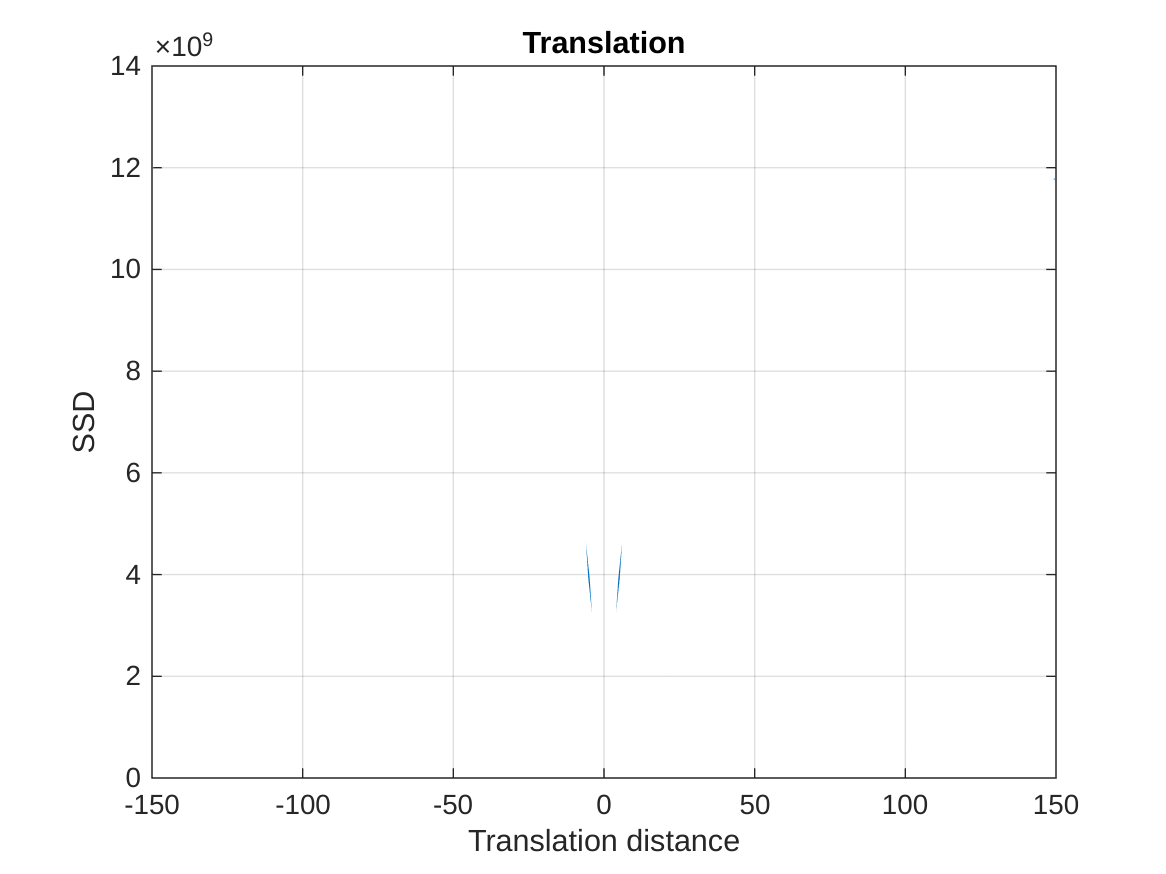

plot(translation_distances, image_ssds_translation)
xlabel("Translation distance")
ylabel("SSD")
title("Translation")
grid on

#### Plot interpretation

Also the translation has the minimum at a movement of 0. Moving the image in any direction increases the difference to its origin monotonously.

### Scaling

scaling_factors = 0.1:0.1:5;

% Initialize result
image_ssds_scaling = zeros(size(scaling_factors));
for i = 1:length(scaling_factors)
    % Scale both dimensions equally by a factor
    transformation_matrix = makeTransf_2D_center(0, 0, 0, scaling_factors(i), scaling_factors(i), center);
    image_transformed = transform_image_2D(transformation_matrix, image, "linear");
    
    % Calculate the pixel differences
    image_diff = image - image_transformed;
    image_ssds_scaling(i) = sum(image_diff(:).^2);
end

#### Plot the pixel differences

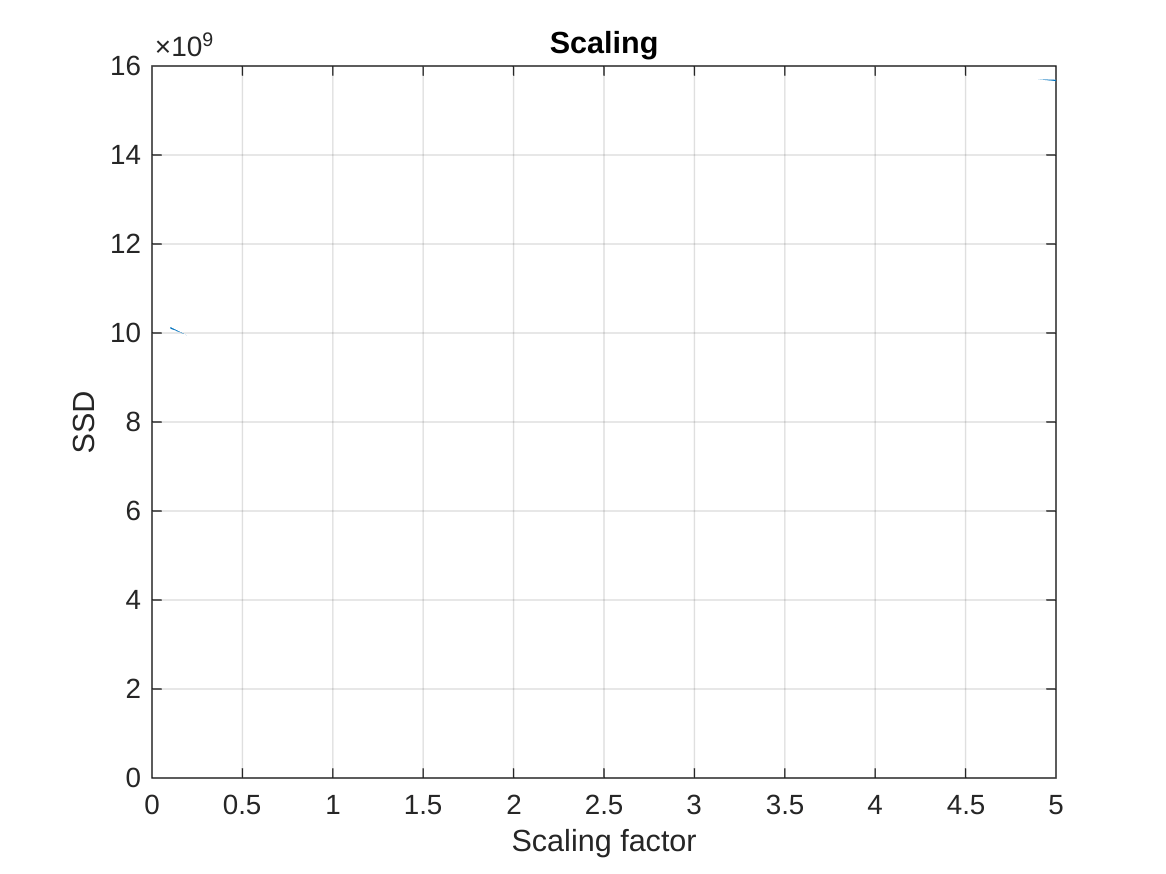

plot(scaling_factors, image_ssds_scaling)
xlabel("Scaling factor")
ylabel("SSD")
title("Scaling")
grid on

#### Plot interpretation

When scaling the image, the least change is applied when using a factor of 1. Going below 1 or above results in steadily increasing differeces in total pixel values. When scaling up, at some point a plateu is reached where practically all pixels are different from the original image.

## Task 2

Rotate an image forward and backward and compare errors made by interpolation

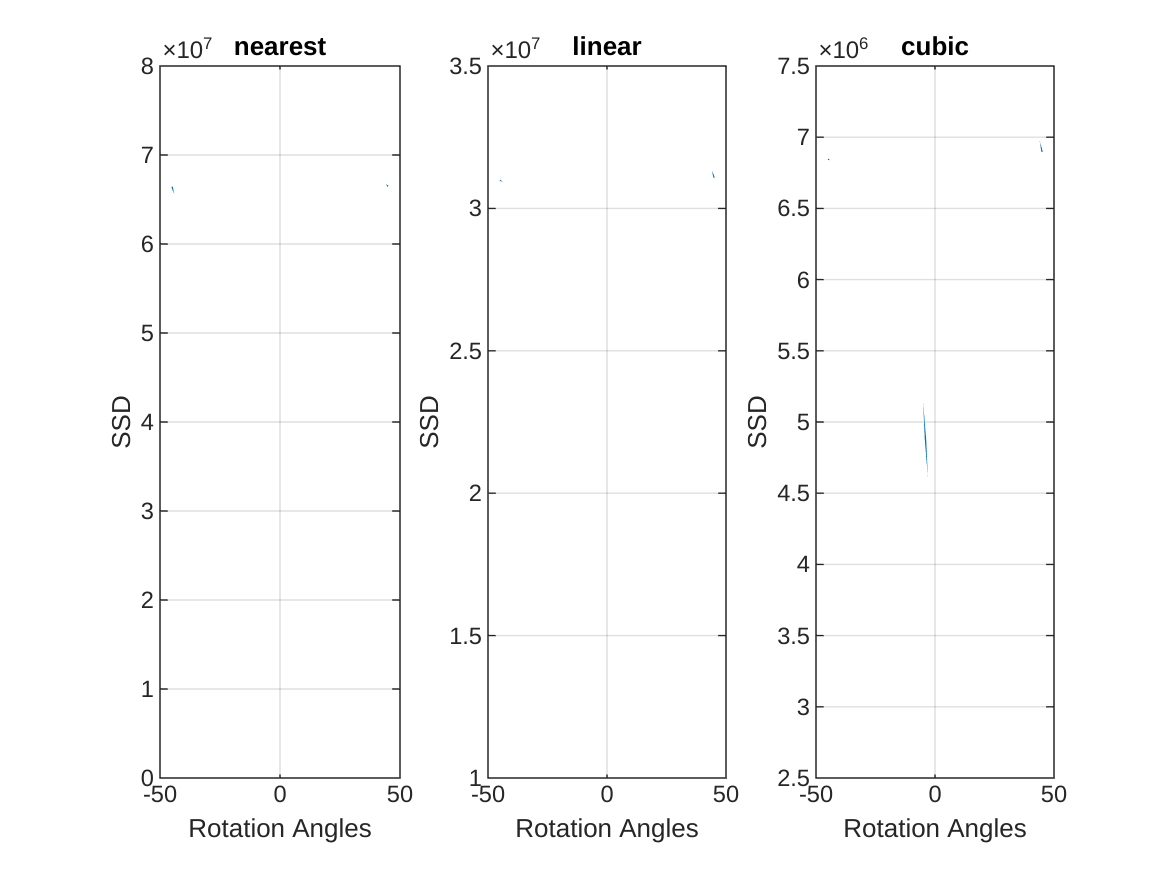

% Define transformation parameters
translation_x = 2.1;
translation_y = 0;
scaling_x = 1.1;
scaling_y = 1.0;
rotation_angles = -45:45;

% Calculate interpolation errors for different options
interpolation_types = ["nearest", "linear", "cubic"];

for plot_index = 1:length(interpolation_types)
    interpolation_type = interpolation_types(plot_index);
    image_ssds = zeros(size(rotation_angles));
    for i = 1:length(rotation_angles)
    % Define the transformations
    transformation_matrix = makeTransf_2D_center(rotation_angles(i), translation_x, translation_y, scaling_x, scaling_y, center);
    transformation_matrix_inverse = inv(transformation_matrix);

    % Transformations with nearest neighbor interpolation
    image_transformed = transform_image_2D(transformation_matrix, image, interpolation_type);
    image_backtransformed = transform_image_2D(transformation_matrix_inverse, image_transformed, interpolation_type);
    image_diff = image - image_backtransformed;
    image_ssds(i) = sum(image_diff(:).^2);
    end
    % Plot the pixel differences
    subplot(1, length(interpolation_types), plot_index);
    plot(rotation_angles, image_ssds)
    xlabel("Rotation Angles")
    ylabel("SSD")
    title(interpolation_type)
    grid on
end

### Plot interpretation

The plot shows the performance of three interpolation methods when applying a transformation and its inverse.

All plots are centered around 0 degrees of rotation (no change) and have a steeply increase in error when applying bigger rotations.

It seems like the original image is preserved better when using a function of higher degree. There is only one irregularity with the nearest neighbor interpolation method, which performs really well for small movements. This is likely the case, because small pixel movements might lead the nearest neighbor being the correct original pixel value.

In general, cubic interpolation has a lower error compared to the other two methods with a maximum squared sum of differences of around 7 * 10⁶ compared to the other interpolation methods having a difference of 7 * 10⁷ and 3 * 10⁷ respectively.